# Exploring Limits and Continuity

## Introduction

The **limit of a function** is a fundamental concept in calculus and analysis concerning the behavior of that function near a particular input.

In this activity we will use the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`limit`](https://au.mathworks.com/help/symbolic/limit.html) to calculate limits of real functions.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read carefuly each section. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

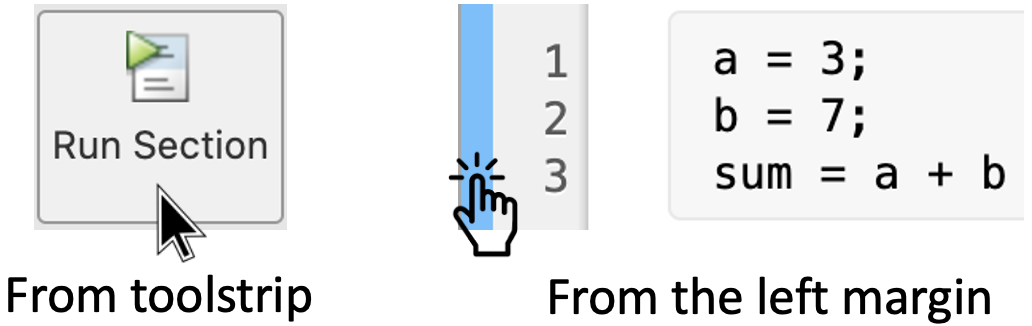

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Calculating limits

### 1.1 Basic form of `limit`

MATLAB provides the `limit` command for calculating limits. In its most basic form, the `limit` command takes an expression as an argument and finds the limit of this expression as the independent variable goes to zero.

For example, let us calculate the limit of a function 

$f\left(x\right)=\frac{x^3 +5}{x^4 +7}$ as $x$ tends to $0$.

The` limit` command falls in the realm of symbolic computing; you need to use the `syms` command to tell MATLAB which symbolic variables you are using. That is:

syms x
limit((x^3 + 5)/(x^4 + 7))

### 1.2. Limit of $f\left(x\right)$ when $x$ tends to $a$

You can also compute limit of a function, as the variable tends to some number other than zero. In general, to calculate


$$\lim_{x\to a} f\left(x\right)$$


we use the command with arguments as: `limit(f, x, a)`. The first "`f`" being the expression, the second "`x`" the variable and the last "`a`" is the number that "`x`" approaches to.

For example, let us calculate the limits of

- $f\left(x\right)=x^2 +5$ as $x$ tends to $3$, and

- $g\left(x\right)=\frac{2x-3}{x-1}$ as $x$ tends to $1$.

Thus we write:

syms x
limit(x^2 + 5, x, 3)
limit((2 * x - 3)/(x - 1), x, 1)

**Remark:** If the $f$ depends only of *one variable*, we can omit it in the code, i.e. `limit(x^2 + 5, 3)`

Also notice that the **Output **of `limit((2 * x - 3/(x - 1))` is `NaN` (not a number). This means that the limit **does not exist!** We can see this geometrically by plotting the graph of $g\left(x\right)=\frac{2x-3}{x-1}$ using the command [`fplot`](https://au.mathworks.com/help/matlab/ref/fplot.html) as follows:

syms x
g0 = (2 * x - 3)/(x - 1);
fplot(x, g0)
xlabel('x')
ylabel('g(x)=(2x-3)/(x-1)')
grid on
axis([-4 4 -8 8])

Another way to confirm that the limit does not exist is by calculating one-sided limits.

### 1.3 One-sided limits

We can also calculate the *left-handed* and *right-handed* limits. These are computed in MATLAB by passing the character strings `'left'` and `'right'` to the `limit` command as the last argument. For example:

syms x
g0 = (2 * x - 3)/(x - 1)
limit(g0, x, 1,'left')
limit(g0, x, 1,'right')

**Remark:** In this case we *cannot *omit the variable "`x`" in the command `limit`. Try it yourself! Delete "`x`" in line 15 or 16 from the previous code and re-run this section to see what happens.

#### 1.3.1 Piecewise functions

In MATLAB we can also calculate limits of piecewise functions. For example, consider the function


$$f\left(x\right)=\left\lbrace \begin{array}{ll}
\frac{3}{2}x-1 & \mathrm{if}\;x<0\\
\frac{e^{x^2 } }{1+x^2 } & \mathrm{if}\;0\le x
\end{array}\right.$$


Before calculating limits, first let us plot this function on the region $\left\lbrack -3,3\right\rbrack \times \left\lbrack -4,4\right\rbrack$ using the commands [`piecewise`](https://au.mathworks.com/help/symbolic/piecewise.html) and [`fplot`](https://au.mathworks.com/help/matlab/ref/fplot.html) as follows:

syms x
f0 = piecewise(x<0, 3/2*x-1, 0<=x, exp(x^2)/(1+x^2))
fplot(f0,'r')
grid on, xlabel('x'), ylabel('y'), axis([-3,3,-4,4])

**Remark:** Notice that all the commands in line 20 are separated with a comma "`,`". Compare with the code for plotting the example from section 1.2.

Now we can calculate the one-sided limits of $f\left(x\right)$. To do this we can make use of the value of the variable `f0`, defined in line 18 from the previous code. Thus we have:

syms x
limit(f0, x, 0, 'left')
limit(f0, x, 0, 'right')

**Questions:** Do these values agree with the graph previously plotted? Is this function continuous or discontinuous at $x=0$?

### 1.4 Limits to Infinity

MATLAB allows you also to calculate limits approaching to infinity. For example, in order to calculate

- 
$$\lim_{x\to \infty } \frac{2x-3}{x-1}$$


- 
$$\lim_{x\to -\infty } \frac{2x-3}{x-1}$$


we just need to write:

syms x
func= (2 * x - 3)/(x - 1)
limit(func, x, Inf)
limit(func, x, -Inf)

**Note:** You can confirm the results geometrically from the plot of section 1.2.

### 1.5 Verification of Basic Properties of Limits

We can also verify the basic properties of limits using the command limit. For example, let us calculate the limit of the functions

- 
$$\frac{3x-5}{x-3}$$


- 
$$x^2 +1$$


as $x$ tends to 5. To do this we write:

syms x
f = (3 * x + 5)/(x - 3);
g = x^2 + 1;
l1 = limit(f, 4)
l2 = limit (g, 4)
lAdd = limit(f + g, 4)
lSub = limit(f - g, 4)
lMult = limit(f * g, 4)
lDiv = limit (f / g, 4)

## 2. Hands on practice

Let's practice what we just learned.

### Activity 1:

Calculate the following limits:

- 
$$\lim_{x\to 1} \frac{3x^4 -4x^3 +1}{{\left(x-1\right)}^2 }$$


- 
$$\lim_{x\to \infty } \frac{x^2 +x-1}{x^3 +x}$$


- 
$$\lim_{x\to -\infty } \frac{x^2 \left(2x+1\right)\left(3x-2\right)}{2x^2 \left(5x-8\right)\left(x+6\right)}$$


- 
$$\lim_{x\to 5} \frac{\sqrt{x-1}-2}{x^2 -25}$$


Write your code here:

### **Activity 2:**

#### Part 1 - Plotting piecewise functions

Use the commands [`piecewise`](https://au.mathworks.com/help/symbolic/piecewise.html) and [`fplot`](https://au.mathworks.com/help/matlab/ref/fplot.html) to plot the graphs of the following functions on the indicated region:

- $f\left(x\right)=\left\lbrace \begin{array}{ll}
3x-1 & \mathrm{if}\;x\le -1\\
\frac{1}{2}x^2  & \mathrm{if}\;-1<x
\end{array}\right.$ on $\left\lbrack -4,4\right\rbrack \times \left\lbrack -10,8\right\rbrack$.

- $g\left(x\right)=\left\lbrace \begin{array}{ll}
\sin \;x & \mathrm{if}\;x<\frac{\pi }{4}\\
\cos \;x & \mathrm{if}\;\frac{\pi }{4}\le x
\end{array}\right.$ on $\left\lbrack -2\pi ,\frac{5}{2}\pi \right\rbrack \times \left\lbrack -1\ldotp 5,1\ldotp 5\right\rbrack$.

**Suggestion:** Remember to use different variables in your code and change the axis scales, and add labels to identify each graph.

Write your code for $f\left(x\right)$ here:

Write your code for $g\left(x\right)$ here:

#### Part 2 - Are these functions continuous or discontinuous?

In section 1.3.1 we discussed how to calculate one-sided limits of piecewise functions.

Determine if $f\left(x\right)$ is continuous or discontinuous at $x=-1$. Write your code here:

Determine if $g\left(x\right)$ is continuous or discontinuous at $x=\frac{\pi }{4}$. Write your code here: